% initial data
Psi_nom = 0.227;
R_a = 0.32;
L_a = 0.0058;
U_nom = 48;
M_nom = 2.6;
J = 0.0145413;

U = -U_nom:0.25*U_nom:U_nom;
M = 0:0.01:8;
M_s = Psi_nom * U / R_a;

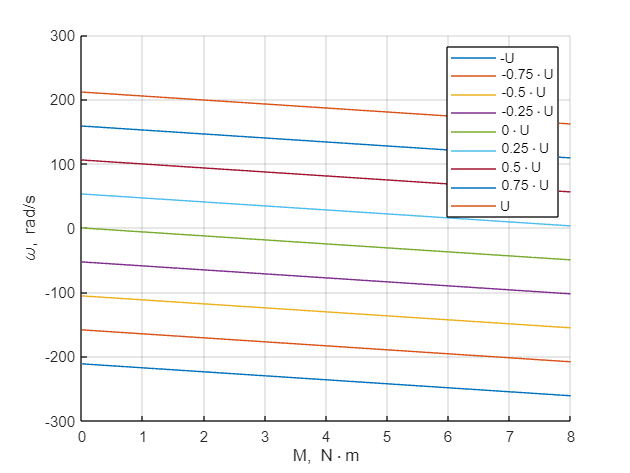

figure;
hold on
for i = 1:numel(U)
    plot(M, U(i)/Psi_nom - R_a/Psi_nom^2*M)
end
hold off
grid on
xlabel("M, N\cdotm"), ylabel("\omega, rad/s")
legend("-U", "-0.75\cdotU", "-0.5\cdotU", "-0.25\cdotU", "0\cdotU", "0.25\cdotU", "0.5\cdotU", "0.75\cdotU", "U")

U = -U_nom:0.01:U_nom;

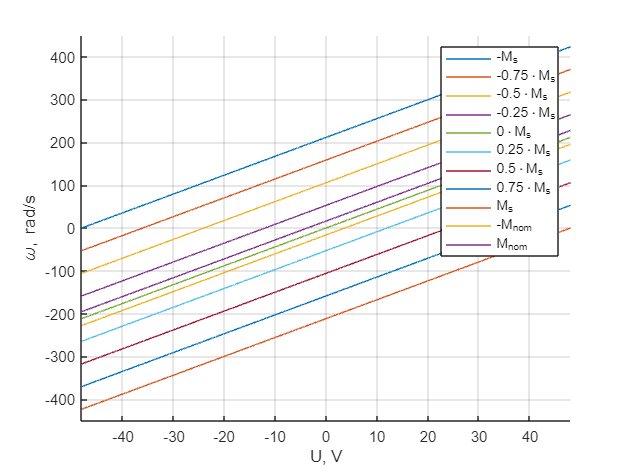

figure;
hold on
for i = 1:numel(M_s)
    plot(U, U/Psi_nom-R_a/Psi_nom^2*M_s(i))
end
plot(U, U/Psi_nom-R_a/Psi_nom^2*M_nom)
plot(U, U/Psi_nom+R_a/Psi_nom^2*M_nom)
hold off
grid on
xlabel("U, V"), ylabel("\omega, rad/s")
legend("-M_s", "-0.75\cdotM_s", "-0.5\cdotM_s", "-0.25\cdotM_s", "0\cdotM_s", "0.25\cdotM_s", "0.5\cdotM_s", "0.75\cdotM_s", "M_s", "-M_{nom}", "M_{nom}")
xlim([-48 48]), ylim([-450 450])

Psi = -Psi_nom:0.25*Psi_nom:Psi_nom;

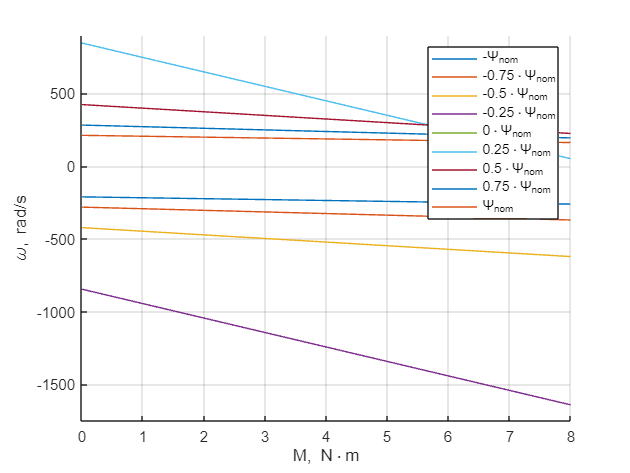

figure;
hold on
for i = 1:numel(Psi)
    plot(M, U_nom/Psi(i) - R_a/Psi(i)^2*M)
end
hold off
grid on
xlabel("M, N\cdotm"), ylabel("\omega, rad/s")
legend("-\Psi_{nom}", "-0.75\cdot\Psi_{nom}", "-0.5\cdot\Psi_{nom}", "-0.25\cdot\Psi_{nom}", "0\cdot\Psi_{nom}", "0.25\cdot\Psi_{nom}", "0.5\cdot\Psi_{nom}", "0.75\cdot\Psi_{nom}", "\Psi_{nom}")
ylim([-1750 900])

Psi = -Psi_nom:0.00001:Psi_nom;

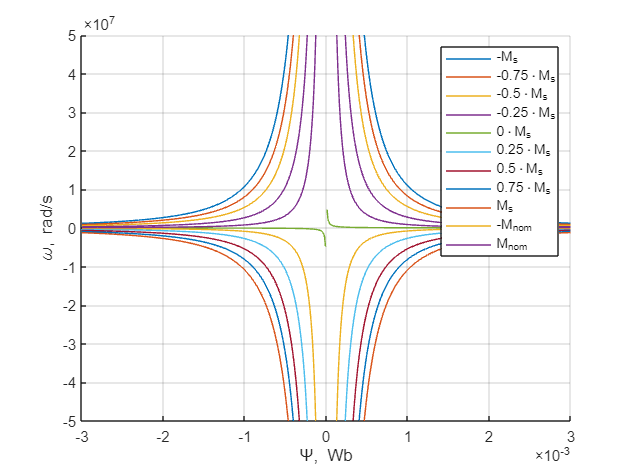

figure;
hold on
for i = 1:numel(M_s)
    plot(Psi, U_nom./Psi - R_a./Psi.^2*M_s(i))
end
plot(Psi, U_nom./Psi - R_a./Psi.^2*M_nom)
plot(Psi, U_nom./Psi + R_a./Psi.^2*M_nom)
hold off
grid on
xlabel("\Psi, Wb"), ylabel("\omega, rad/s")
legend("-M_s", "-0.75\cdotM_s", "-0.5\cdotM_s", "-0.25\cdotM_s", "0\cdotM_s", "0.25\cdotM_s", "0.5\cdotM_s", "0.75\cdotM_s", "M_s", "-M_{nom}", "M_{nom}")
xlim([-0.003 0.003])
ylim([-50000000, 50000000])

R = R_a:0.25*R_a:3*R_a;

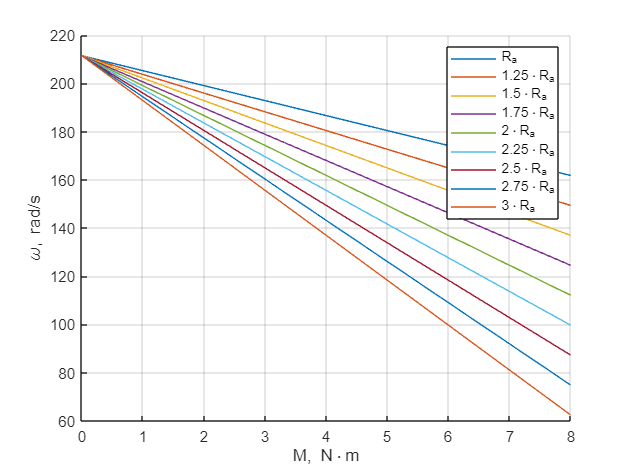

figure;
hold on
for i = 1:numel(R)
    plot(M, U_nom/Psi_nom - R(i)/Psi_nom^2.*M)
end
hold off
grid on
xlabel("M, N\cdotm"), ylabel("\omega, rad/s")
legend("R_{a}", "1.25\cdotR_{a}", "1.5\cdotR_{a}", "1.75\cdotR_{a}", "2\cdotR_{a}", "2.25\cdotR_{a}", "2.5\cdotR_{a}", "2.75\cdotR_{a}", "3\cdotR_{a}")

R = R_a:0.001:3*R_a;

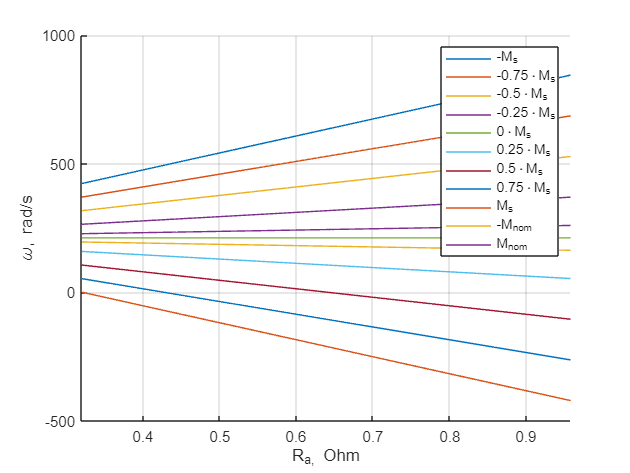

figure;
hold on
for i = 1:numel(M_s)
    plot(R, U_nom./Psi_nom - R./Psi_nom.^2*M_s(i))
end
plot(R, U_nom/Psi_nom - R./Psi_nom.^2*M_nom)
plot(R, U_nom/Psi_nom + R./Psi_nom.^2*M_nom)
hold off
grid on
xlabel("R_a, Ohm"), ylabel("\omega, rad/s")
legend("-M_s", "-0.75\cdotM_s", "-0.5\cdotM_s", "-0.25\cdotM_s", "0\cdotM_s", "0.25\cdotM_s", "0.5\cdotM_s", "0.75\cdotM_s", "M_s", "-M_{nom}", "M_{nom}")
xlim([0.32 0.958])